# German Stocks - Hypothesis Tests

## 1.

Load the table stored in the file `daxReturns.mat`.

load daxReturns

## 2.

Check if the index returns (first variable) are normally distributed. Use different tests to validate your conclusion. 

[HN(1),pN(1)] = lillietest(daxReturns.DAX);

[HN(2),pN(2)] = jbtest(daxReturns.DAX);

[HN(3),pN(3)] = adtest(daxReturns.DAX);

disp([HN', pN'])

    1.0000    0.0010
    1.0000    0.0010
    1.0000    0.0005


## 3.

Fit a *t-location scale* distribution to the DAX returns, and use a Q-Q-plot (`qqplot`) to find out if it is reasonable to use a *t-location scale *distribution to model the DAX returns.

daxDist = fitdist(daxReturns.DAX, 'tlocationscale')

daxDist =   tLocationScaleDistribution

  t Location-Scale distribution
       mu = 0.000432699   [-0.000435475, 0.00130087]
    sigma =   0.0108462   [0.00993237, 0.0118441]
       nu =     3.18457   [2.50765, 4.04422]


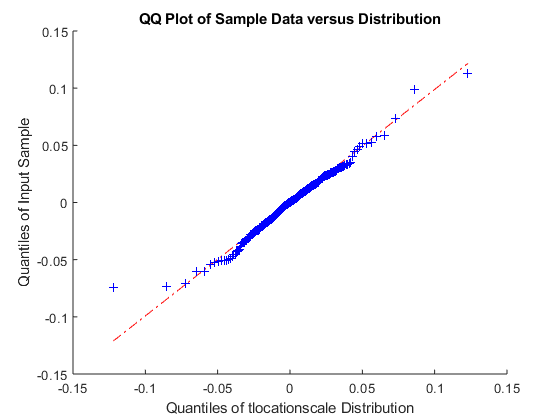

qqplot(daxReturns.DAX,daxDist)

## 4.

Test if the mean of the DAX returns is zero.  Use your findings from step 2 to determine a suitable test method. 

[pZ(1),HZ(1)] = signtest(daxReturns.DAX);
[pZ(2),HZ(2)] = signrank(daxReturns.DAX);
disp([HZ', pZ'])

         0    0.1538
         0    0.6116


## 5.

Test if the returns of Fresenius and Fresenius Medical are identically distributed.

[HSame,pSame] = kstest2(daxReturns.Fresenius, daxReturns.FreseniusMedical);
disp([HSame, pSame])

    1.0000    0.0104
